# Demo 1: GLM temporal stimulus

Simulate and fit a single-neuron GLM with 1D (temporal) filter with exponential nonlinearity.

Start by adding repository functions to current path, assuming the current directory is set to the respository home (e.g. ~/Github/GLMspiketools)

setpaths_GLMspiketools

### 1. Create a model of simulated neuron

Define the simulation parameters, including the length of the stimulus filter in time. The default temporal stimulus filter is constructed from the difference between two gamma pdfs (probability density functions) with different scale parameters ($\theta$). The post-spike filter is contructed from the weighted sum of raised cosine basis functions.

dtStim = 0.01;   % Bin size for stimulus (in seconds).  (Equiv to 100Hz frame rate)
dtSp = 0.001;    % Bin size for simulating model & computing likelihood (must evenly divide dtStim);
nkt = 30;        % Number of time bins in stimulus filter k

sim_mdl = makeSimStruct_GLM(nkt, dtStim, dtSp); 

Show the model properties of the simulation:

- Top left: stimulus filter 

- Top right: post-spike filter

- Bottom right: unweighted raised cosine basis functions from which post-spike filter is constructed

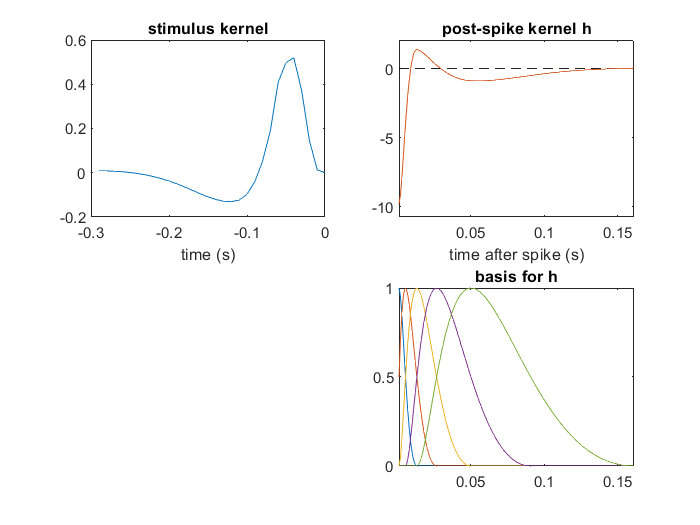

figure('name', 'model params')

ttk = dtStim * (-nkt+1:0)';  % time relative to spike of stim filter taps
[~, ~, ihbasis] = makeBasis_PostSpike(sim_mdl.ihbasprs, dtSp);

subplot(221)
plot(ttk, sim_mdl.k)
title('stimulus kernel')
xlabel('time (s)')

subplot(222); 
plot(sim_mdl.iht, sim_mdl.iht*0, 'k--', sim_mdl.iht, sim_mdl.ih);
title('post-spike kernel h')
axis tight
xlabel('time after spike (s)')
set(gca, 'ylim',[min(sim_mdl.ih)*1.1 max(sim_mdl.ih)*1.5])

subplot(224)
plot(sim_mdl.iht, ihbasis)
title('basis for h')
axis tight

### 2. Generate training data

Create a random  stimulus and use the simulation model to generate a train of spikes in response. 

rng('default')
rng(0)

stim_length = 50000;                        % Stimulus length (frames); more samples gives better fit
stim_width = 1;                             % Stimulus width (pixels); must match # pixels in stim filter
stim = rand(stim_length, stim_width)*2-1;

[~, binary_spike_vector, I_total, Istm] = simGLM(sim_mdl, stim); 

Generate a figure with three rows that shows the first 0.5 seconds of:

- Top: the stimulus

- Middle: spiking activity shown as conditional intensity of firing (blue line) and the occurence of individual spikes (black dots)

- Bottom: outputs of stimulus and post-spike filters

The figure illustrates how the conditional intensity is a continuous function of the stimulus, even when the neuron isn't producing any output; whereas the post-spike filter only plays a role after the neuron generates a spike.

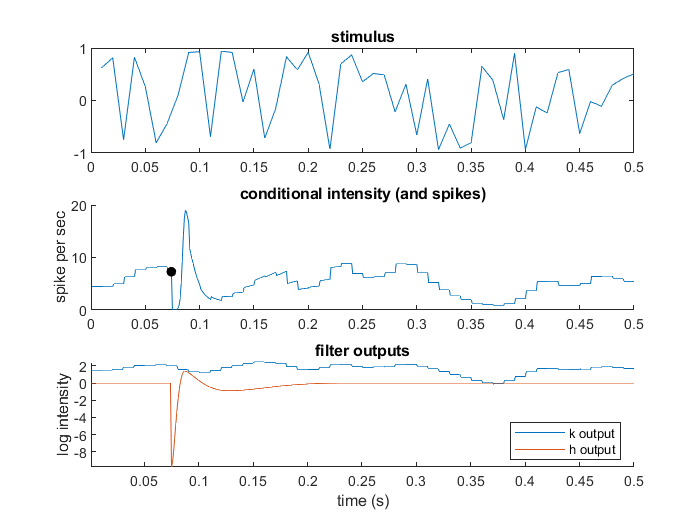

figure('name','training data')

tlen = 0.5;
ttstim = dtStim : dtStim : tlen;
iistim = 1 : length(ttstim);

subplot(311)
plot(ttstim, stim(iistim))
title('stimulus')

plot_times = dtSp : dtSp : tlen; 
plot_indices = 1 : length(plot_times);
spike_indices = binary_spike_vector(plot_indices) > 0;

subplot(312)
hold on
semilogy( plot_times, exp(I_total(plot_indices)))
semilogy( plot_times(spike_indices), exp(I_total(spike_indices)), 'k.', 'markersize', 20)
ylabel('spike per sec')
title('conditional intensity (and spikes)')

subplot(313)
hold on
Isp = I_total-Istm; % total spike-history filter output
plot(plot_times, Istm(plot_indices))
plot(plot_times, Isp(plot_indices))
axis tight
legend('k output', 'h output', 'location', 'best')
xlabel('time (s)')
ylabel('log intensity')
title('filter outputs')

### 3. Initialize model fitting parameters

We begin by computing the spike triggered average (STA) that provides the initial estimate of the stimulus filter

samps_coarse = sum(reshape(binary_spike_vector, [], stim_length), 1)';  % bin spikes in bins the size of stimulus
spike_trig_avg = simpleSTC(stim, samps_coarse, nkt); 
spike_trig_avg = reshape(spike_trig_avg, nkt, []);                      % reshape it to match dimensions of true filter

Set the fitting parameters, including the bases for representing the stimulus filter (k) and spike history filter (h)

nkbasis = 8;        % number of basis vectors for representing k
nhbasis = 8;        % number of basis vectors for representing h
hpeakFinal = .1;    % time of peak of last basis vector for h
exptmask = [];      % set mask, optional e.g. [1 slen*dtStim];  % data range to use for fitting (in s).

Making a data structure for GLM fitting from the STA, settings and spike data. Note the random intialization of spike history weights.

initial_mdl = makeFittingStruct_GLM(dtStim, dtSp, nkt, nkbasis, spike_trig_avg, nhbasis, hpeakFinal);

initial_mdl.sps = binary_spike_vector;              % Insert binned spike train into fitting struct
initial_mdl.ihw = randn(size(initial_mdl.ihw))*1;   % initialize spike-history weights randomly
initial_mdl.mask = exptmask;                        % insert mask (optional)

Get baseline model fit at initial parameters so that the effect of optimization can be monitorred.

[negloglival0, ~] = neglogli_GLM(initial_mdl, stim);
fprintf('Initial negative log-likelihood: %.5f\n', negloglival0);

Initial negative log-likelihood: 138.71319


### 4. Fit using Maximum Likelihood 

Requires optimization toolbox and the 'fminunc' function

fminunc_opts = {'display', 'iter', 'maxiter', 100};
[fitted_mdl, ~] = MLfit_GLM(initial_mdl, stim, fminunc_opts); 


                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0           -99.7502                      1.89e+03                
     1           -99.7502             10       1.89e+03           5
     2           -99.7502            2.5       1.89e+03           0
     3           -1312.67          0.625       1.41e+03           0
     4           -1801.94           1.25       1.18e+03           5
     5            -2186.6           1.25            203           4
     6           -2338.99            2.5           38.8           6
     7           -2430.53        4.29684           40.7           6
     8           -2445.98        2.78688           17.2           7
     9           -2448.62        1.70893           3.55           8
    10            -2449.3       0.463936           3.03           8
    11           -2449.44       0.247193          0.863           8
    12           -2449.47       0.100368        

## 5. Plot results

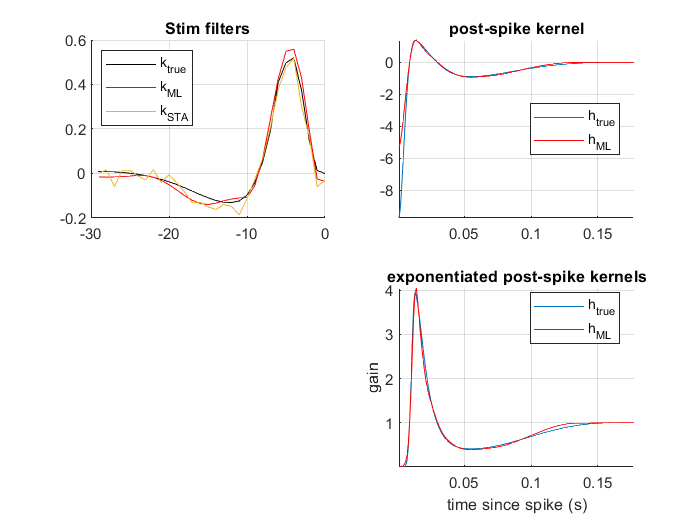

ttk = -nkt+1:0; % time bins for stimulus filter

figure('name','GLM results')

% Plot stimulus filter 
subplot(221) 
hold on
grid on

plot(ttk, sim_mdl.k, 'k')
plot(ttk, fitted_mdl.k, 'r');
plot(ttk, spike_trig_avg./norm(spike_trig_avg)*norm(sim_mdl.k))

title('Stim filters')
legend('k_{true}', 'k_{ML}', 'k_{STA}', 'location', 'northwest');

% Plot post-spike kernel
subplot(222)
hold on
grid on

plot(sim_mdl.iht, sim_mdl.ih)
plot(fitted_mdl.iht, fitted_mdl.ih,'r')

legend('h_{true}', 'h_{ML}', 'location', 'best')

title('post-spike kernel')
axis tight

% Plot exponentiated post-spike kernel
subplot(224)
hold on
grid on

plot(sim_mdl.iht, exp(sim_mdl.ih))
plot(fitted_mdl.iht, exp(fitted_mdl.ih),'r')

legend('h_{true}', 'h_{ML}', 'location', 'best')

title('exponentiated post-spike kernels');
xlabel('time since spike (s)');
ylabel('gain'); axis tight;



% Errors in STA and ML estimate (subspace angle between true k and estimate)
fprintf('Filter estimation error (in radians)\n  sta: %.3f\n   ML: %.3f\n', ...
    subspace(sim_mdl.k,spike_trig_avg), subspace(sim_mdl.k,fitted_mdl.k));

Filter estimation error (in radians)
  sta: 0.184
   ML: 0.108
